##  TAREFA 3: CONTROLE PID DE UM SISTEMA DE 2ª ORDEM POR ALOCAÇÃO DE POLOS

## Parte A 

A-1)  Obtenha a funçãode transferência para uma máquina CC considerando a tensão de campo constant, a variável de entrada como a tensão de armadura e a variável de saída como sendo a velocidade angular da máquina. Considerando os seguintes parâmetros:


$$\frac{R}{L} = 10$$
   
$$K_{T} = 15
$$
   
$$K_{B} = 0.3
$$
    
$$J = 15$$
    
$$B = 5$$


Quais são os polos em malha aberta?

A-2) Calcule um controlador PID para a máquina do item anterior, de modo a alocar os polos do sistemaem malha fechadanos seguintes pontos:


$$\lambda_{1} = -5+j$$
     
$$\lambda_{2} = -5-j$$
     
$$\lambda_{3} = -7$$


A-3) Repita o item anterior considerando os seguintes pontos:


$$\lambda_{1} = -5.5+j1.5$$
     
$$\lambda_{2} = -5.5-j1.5$$
     
$$\lambda_{3} = -1.2$$


## Parte B

B-1) Simule a máquina CC com os parâmetros da questão A-1. Obtenha a saída (velocidade angular) em função do tempo para uma entrada degrau unitário. Qual o erro em regime?

B-2) Acople à simulação anterior o controlador obtido na questão A-2. Obtenha a saída (velocidade angular) e entrada (tensão de armadura) em função do tempo, considerando que a referência é um degrau unitário.

B-3) Repita a questão anterior utilizando o controlador obtido na questão A-3. Compare o desempenho do motor em relação ao item A-2.

**Resolução A-1)     **                       

%% Função de transferências de malha aberta

A função de transferência em malha aberta é dada por:


$$G(s) = \frac{K_{T}}{(Ls+R)(Js+B)}$$



$$G(s) = \frac{K_{T}}{LJs^2+s(LB+RJ)+RB}$$



$$G(s) = \frac{\frac{K_{T}}{LJ}}{s^2+s(\frac{B}{J}+\frac{R}{L})+\frac{RB}{LJ}}$$


Substituindo os valores conforme o item A-1:


$$G(s) = \frac{10}{s^2+10.33s+3.33}$$


Assim, os polos em malha aberta são: x1 = -0.3331 e x2 = -9.9969.

**Resolução A-2)  **

A equação característica desejada D(s), obtida do acoplamento do controlador PID à planta, que atende aos polos desejados de malha fechada é dada por:


$$D(s) = (s-\lambda_{1})(s-\lambda_{2})(s-\lambda_{3}) = s^3+ \alpha_{2}s^2 + \alpha_{1}s + \alpha_{0} $$


Substituindo os valores dos polos desejadas conforme item A-2:


$$D(s) = (s+5-j)(s+5+j)(s+7) $$



$$D(s) = (s^2+5s+js+5s+25+5j-js-5j+1)(s+7) $$



$$D(s) = (s^2+10s+26)(s+7) $$



$$D(s) = s^3+10s^2+26s+7s^2+70s+182$$



$$D(s) = s^3+17s^2+96s+182$$



$$D(s) = s^3+17s^2+96s+182= s^3+ \alpha_{2}s^2 + \alpha_{1}s + \alpha_{0} $$



$$\alpha_{2} =17
 $$
    
$$\alpha_{1} =96
 $$
    
$$\alpha_{0} =182
 $$


a2 = 17;
a1 = 96;
a0 = 182;

psi2wn = 31/3;
wn2 = 95/15;
K = 10;

Gmf = tf(K,[1 psi2wn wn2])


Gmf =
 
           10
  ---------------------
  s^2 + 10.33 s + 6.333
 
Continuous-time transfer function.



Kp = (a1-wn2)/K;
Ti = (a1-wn2)/a0;
Td = (a2-psi2wn)/(a1-wn2);

GanhoC1 = [Kp Ti Td]

GanhoC1 =     8.9667    0.4927    0.0743

**Resolução A-3)  **

A equação característica desejada D(s), obtida do acoplamento do controlador PID à planta, que atende aos polos desejados de malha fechada é dada por:


$$D(s) = (s-\lambda_{1})(s-\lambda_{2})(s-\lambda_{3}) = s^3+ \alpha_{2}s^2 + \alpha_{1}s + \alpha_{0} $$


Substituindo os valores dos polos desejadas conforme item A-3:


$$D(s) = (s+5.5-j1.5)(s+5.5+j1.5)(s+1.2) $$


p1 = [1, 5.5-1.5j];
p2 = [1, 5.5+1.5j];
p3 = [1 1.2];
R1 = conv(p1,p2);
R2 = conv(R1,p3)

R2 =     1.0000   12.2000   45.7000   39.0000


$$D(s) = s^3+12.2s^2+45.7s+39$$



$$D(s) = s^3+12.2s^2+45.7s+39= s^3+ \alpha_{2}s^2 + \alpha_{1}s + \alpha_{0} $$



$$\alpha_{2} =12.2
 $$
    
$$\alpha_{1} =45.7
 $$
    
$$\alpha_{0} =39
 $$


a2 = 12.2;
a1 = 45.7;
a0 = 39;

psi2wn = 31/3;
wn2 = 95/15;
K = 10;

Kp = (a1-wn2)/K;
Ti = (a1-wn2)/a0;
Td = (a2-psi2wn)/(a1-wn2);

GanhoC2 = [Kp Ti Td]

GanhoC2 =     3.9367    1.0094    0.0474

**Resolução B-1)**

    A função de transferência em malha aberta do sistema é:


$$G(s) = \frac{10}{s^2+10.33s+3.33}$$


% Plote das Respostas ao Degrau

Gráficos de respostas do sistema à entrada degrau.

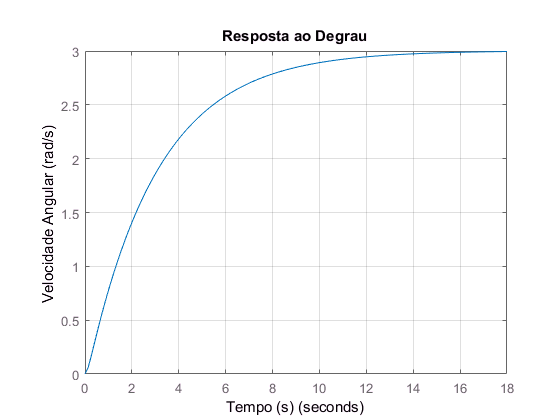

num = [10];
den = [1 10.33 3.33];
G = tf(num, den);
figure(1);
step(G);
xlabel('Tempo (s)');
ylabel('Velocidade Angular (rad/s)');
title('Resposta ao Degrau');
grid on; grid minor; 

Nota-se que houve um erro em regime (erro = referência - saída) de -2 rad/s, ou seja, em resposta à entrada degrau unitário, o sistema apresentou uma saída de 3 rad/s.

**Resolução B-2)**

    A função de transferência resultante em malha fechada com o controlador PID acoplado à planta é dada por:


$$G(s) = \frac{KK_p(T_ds^2+s+\frac{1}{T_i})}{s^3+(2\xi w_n+KK_pT_d)s^2+(w_n+KK_p)s+\frac{KK_p}{T_i}}$$


% Plote das Respostas ao Degrau

Gráficos de respostas do sistema à entrada degrau.

clear('num','den')
psi2wn = 31/3;
wn2 = 95/15;
K = 10;

Kp = GanhoC1(1); Ti = GanhoC1(2); Td = GanhoC1(3);
num = K*Kp*[Td 1 1/Ti];
den = [1, psi2wn+K*Kp*Td, wn2+K*Kp, K*Kp/Ti ];
GGc = tf(num, den)


GGc =
 
  6.667 s^2 + 89.67 s + 182
  -------------------------
  s^3 + 17 s^2 + 96 s + 182
 
Continuous-time transfer function.



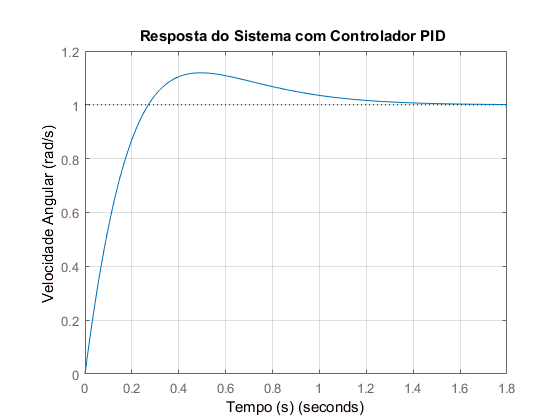

figure(2);
step(GGc);
xlabel('Tempo (s)');
ylabel('Velocidade Angular (rad/s)');
title('Resposta do Sistema com Controlador PID ');
grid on; grid minor; 

stepinfo(GGc)

ans =         RiseTime: 0.1976
    SettlingTime: 1.1495
     SettlingMin: 0.9167
     SettlingMax: 1.1189
       Overshoot: 11.8941
      Undershoot: 0
            Peak: 1.1189
        PeakTime: 0.4974

O sistema levou em torno de 1,15 s para o assentamento em torno da referência, apresentando um sobressinal de aproximadamente 12%. Como esperado, o controlador PID garante o erro nulo em regime.

**Resolução B-3)**

    A função de transferência resultante em malha fechada com o controlador PID acoplado à planta é dada por:


$$G(s) = \frac{KK_p(T_ds^2+s+\frac{1}{T_i})}{s^3+(2\xi w_n+KK_pT_d)s^2+(w_n+KK_p)s+\frac{KK_p}{T_i}}$$


% Plote das Respostas ao Degrau

Gráficos de respostas do sistema à entrada degrau.

clear('num','den','GGc')
psi2wn = 31/3;
wn2 = 95/15;
K = 10;

Kp = GanhoC2(1);
Ti = GanhoC2(2);
Td = GanhoC2(3);
num = K*Kp*[Td 1 1/Ti];
den = [1, psi2wn+K*Kp*Td, wn2+K*Kp, K*Kp/Ti ];
GGc = tf(num, den)


GGc =
 
    1.867 s^2 + 39.37 s + 39
  ----------------------------
  s^3 + 12.2 s^2 + 45.7 s + 39
 
Continuous-time transfer function.



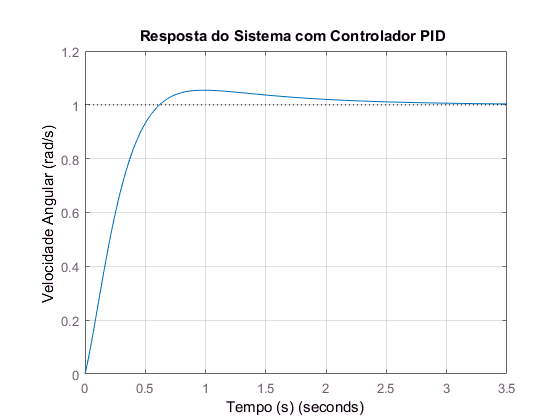

figure(3);
step(GGc);
xlabel('Tempo (s)');
ylabel('Velocidade Angular (rad/s)');
title('Resposta do Sistema com Controlador PID ');
grid on; grid minor; 

stepinfo(GGc)

ans =         RiseTime: 0.4161
    SettlingTime: 2.0104
     SettlingMin: 0.9061
     SettlingMax: 1.0544
       Overshoot: 5.4378
      Undershoot: 0
            Peak: 1.0544
        PeakTime: 0.9880

A resposta do sistema com o controlador PID na malha fez com que o sistema obtivesse um tempo de resposta de 0.42 s, levando pouco mais de 2 s para o assentamento em torno da referência, porém obteve um sobressinal de 5,4%. Como esperado, o controlador PID garante o erro nulo em regime.

## Conclusões

A resposta em malha aberta do sistema apresenta erro em regime permante, sendo necessária a implementação de um controlador PID à malha do sistema, a fim de garantir o rastreamento da referência e, consequentemente, erro nulo em regime. O primeiro controlador conseguiu uma resposta mais rápida porém causou um sobressinal também maior ao sistema.  O segundo controlador obteve um sobressinal praticamente desprezível em troca de um tempo de resposta um pouco maior que o primeiro. A escolha do controlador deve ser baseada na aplicação à qual se destina. Se não for desejável que o sistema apresente sobressinal e que se trate de uma processo que exige precisão, o segundo controlador seria mais preferível. Se o que importa é o tempo de recuperação do sistema a pertubações, o primeiro controlador pode ser utilizado.